## USE "Run Section"

## Let's simulate an acquisition equipment.

% Load data.
% This dataset represents the output of the acquisition equipment.

addpath('data')
load('DatasetENEEB.mat')

% What we know about the data:
sampling_freq=4;

% You should see TRAIN, TEST1, TEST2 and chans_label 
% in MATLAB's Workspace.

## Let's see what is inside each variable.

traindata is a 41x1280

[train_rows, train_cols]=size(TRAIN);
[num_chans]=numel(chans_labels);

fprintf('Our training set has %i samples, and %i channels.\n', train_cols, num_chans);

Our training set has 1280 samples, and 40 channels.


## Checking the training data.

First we have to select a channel.

chan_idx=3;

Now we can plot it over time.

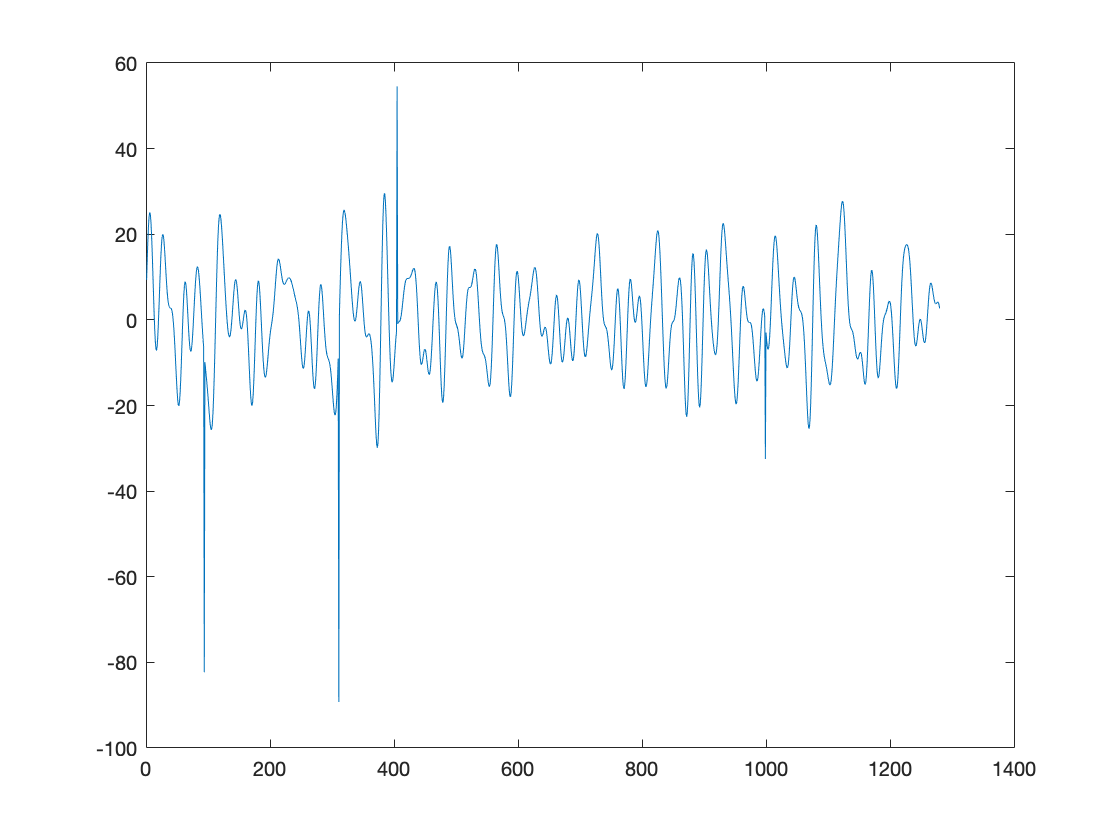

figure, 
plot(TRAIN(chan_idx,:))

Re-arrange the plot considering what we know.

Sampling_Freq=4Hz.

If possible , make a "prettier" plot.

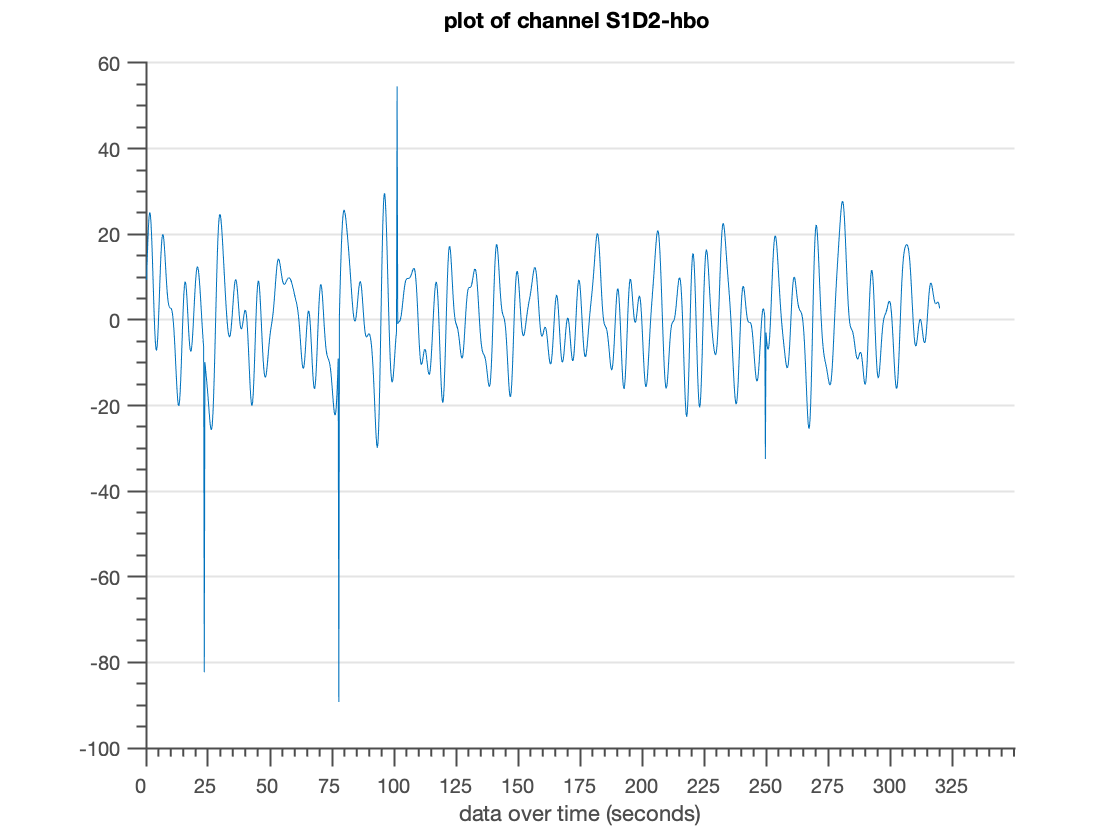

int_t=100;
set(gca, ...
  'Box'         , 'off'     , ...
  'TickDir'     , 'out'     , ...
  'TickLength'  , [.02 .02] , ...
  'XMinorTick'  , 'on'      , ...
  'YMinorTick'  , 'on'      , ...
  'YGrid'       , 'on'      , ...
  'XColor'      , [.3 .3 .3], ...
  'YColor'      , [.3 .3 .3], ...
  'XTick'       , 0:int_t:train_cols+int_t, ...
  'XTickLabel'  , 0:int_t/sampling_freq:(train_cols+int_t)/sampling_freq, ...
  'LineWidth'   , 1         );

ylim=get(gca, 'ylim');

xlabel('data over time (seconds)')

title(sprintf('plot of channel %s \n', chans_labels{chan_idx}))

If you look closely, the matrix TRAIN has 41 lines. The last one represents the task.

Let's edit the figure and add the condition.

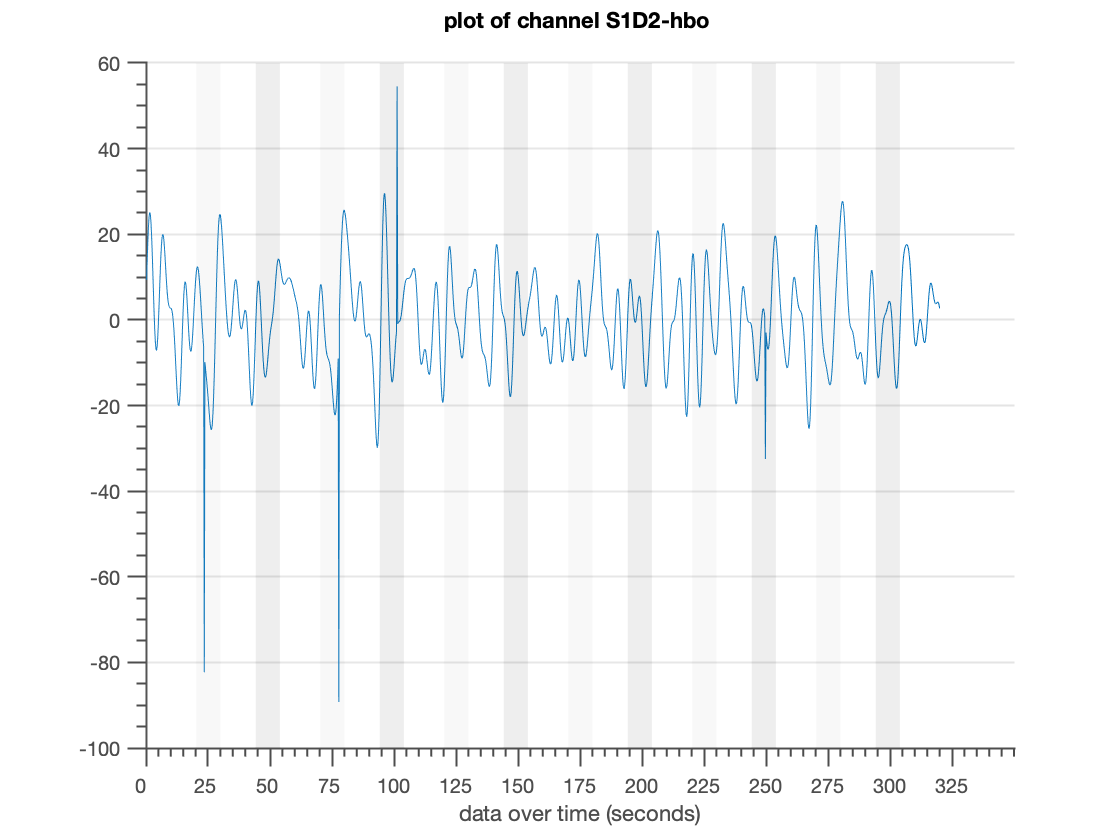

hold on;

idxs=find(diff(TRAIN(end,:)));
st_int=1;
colors=[255, 255, 255;
    190, 190, 190;
    90, 90, 90]/255;

for i=1:numel(idxs)
    end_int=idxs(i);
    
    p=patch([st_int end_int end_int st_int],...
        [ylim(1) ylim(1)  ylim(2) ylim(2)],...
        colors(TRAIN(end,st_int)+1,:));
    set(p, 'FaceAlpha', 0.1,...
           'EdgeColor', 'none')   
    st_int=end_int+1;
end

There are several moments that represent outliers (data points that differ significantly from other observations).

How can we identify them? clean them?


ch_idx=3

ch_idx = 3

outlcoef=3

outlcoef = 3

                
% outlier detection.
datasegment=TRAIN(ch_idx,:);

% compute sliding window mean.
m_data=mean(datasegment);
std_data=std(datasegment);

outliers_idxs=find(abs(m_data-datasegment)>outlcoef*std_data);
if(~isempty(outliers_idxs))
    fprintf('found outliers in ch %i \n', ch)
end

found outliers in ch 35 



for i =1:length(outliers_idxs)
    if datasegment(outliers_idxs(i)) > m_data
        datasegment(outliers_idxs(i))=m_data+std_data*2.5;
    else
        datasegment(outliers_idxs(i))=m_data-std_data*2.5;
    end
end


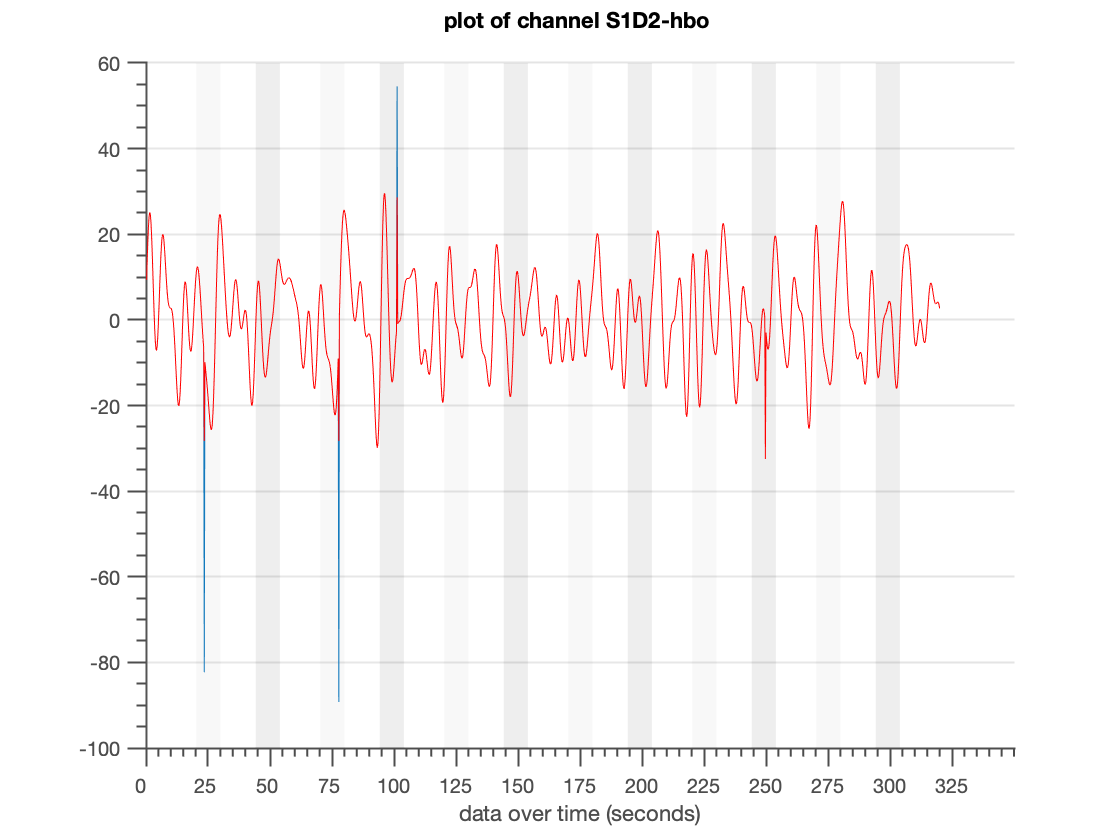


plot(datasegment, 'r')


movingavwindow=5;

% low pass filter - moving average of x samples (pr channel)
datasegmentcleaned=movmean(datasegment,movingavwindow)

datasegmentcleaned =    13.9730   15.9539   17.5986   20.7498   22.8472   23.7135   23.2848   21.6102   18.8421   15.2212   11.0573    6.7075    2.5486   -1.0556   -3.7880   -5.4122   -5.7981   -4.9375   -2.9449   -0.0429    3.4650    7.2281   10.8894   14.1212   16.6573   18.3173   19.0184   18.7777   17.7047   15.9819   13.8382   11.5208    9.2614    7.2498    5.6131    4.4049    3.6052    3.1308    2.8514    2.6119    2.2527    1.6300    0.6309   -0.8135   -2.7201   -5.0477   -7.6948  -10.5019  -13.2590  -15.7220


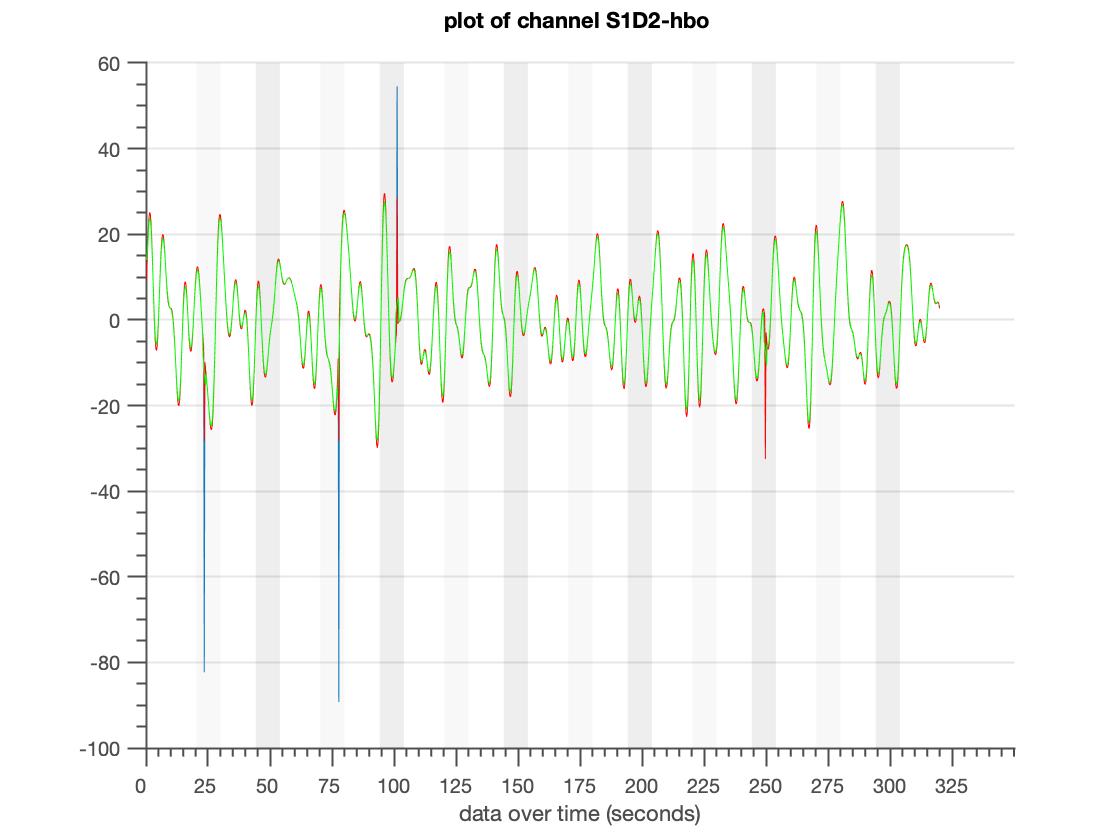


plot(datasegmentcleaned, 'g')